## **Lab 1**

#### Physics 434 

#### Tyler Flom

#### October 11, 2020

### 1) Standard Normal Distributions:

**A) Introduction to Normal Distributions**

In a normal distribution, or a Gaussian distribution, the probability density function is: 

$P\left(x\right)=\frac{1}{\sigma \sqrt{2\pi }}e^{-\frac{{\left(x-\mu \right)}^2 }{2\sigma^2 }}$ , where $\mu$ is the mean and $\sigma$ is the standard deviation. 

  For a standard normal distribution: 

$\mu =0$, $\sigma =1$

 We also change variables to z where: 

$z=\frac{\left(x-\mu \right)}{\sigma }$ and $d\;z\;=\frac{d\;x}{\sigma }$

This results in a new probability density function specifically for standard normal distributions: 


$$P\left(x\right)\;d\;x=\frac{1}{\sqrt{2\pi }}e^{-\frac{z^2 }{2}} \;d\;z$$


prob_succ = 0;
sigma = 1

sigma = 1

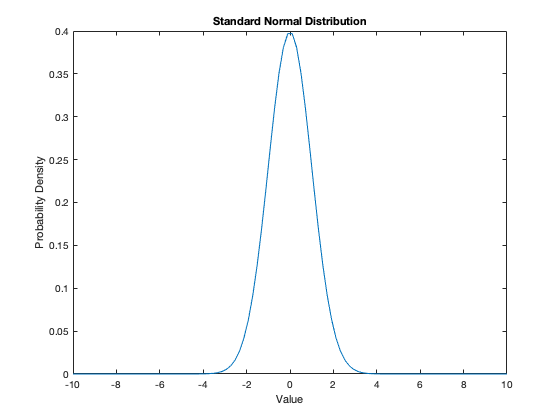


x = linspace(-10,10,100);
z = (x-prob_succ)/sigma;

P_density=(1/(sigma*sqrt(2*pi))*exp(-(z).^2/(2)));
figure(1);
plot(x,P_density);
title('Standard Normal Distribution');
ylabel('Probability Density');
xlabel('Value');

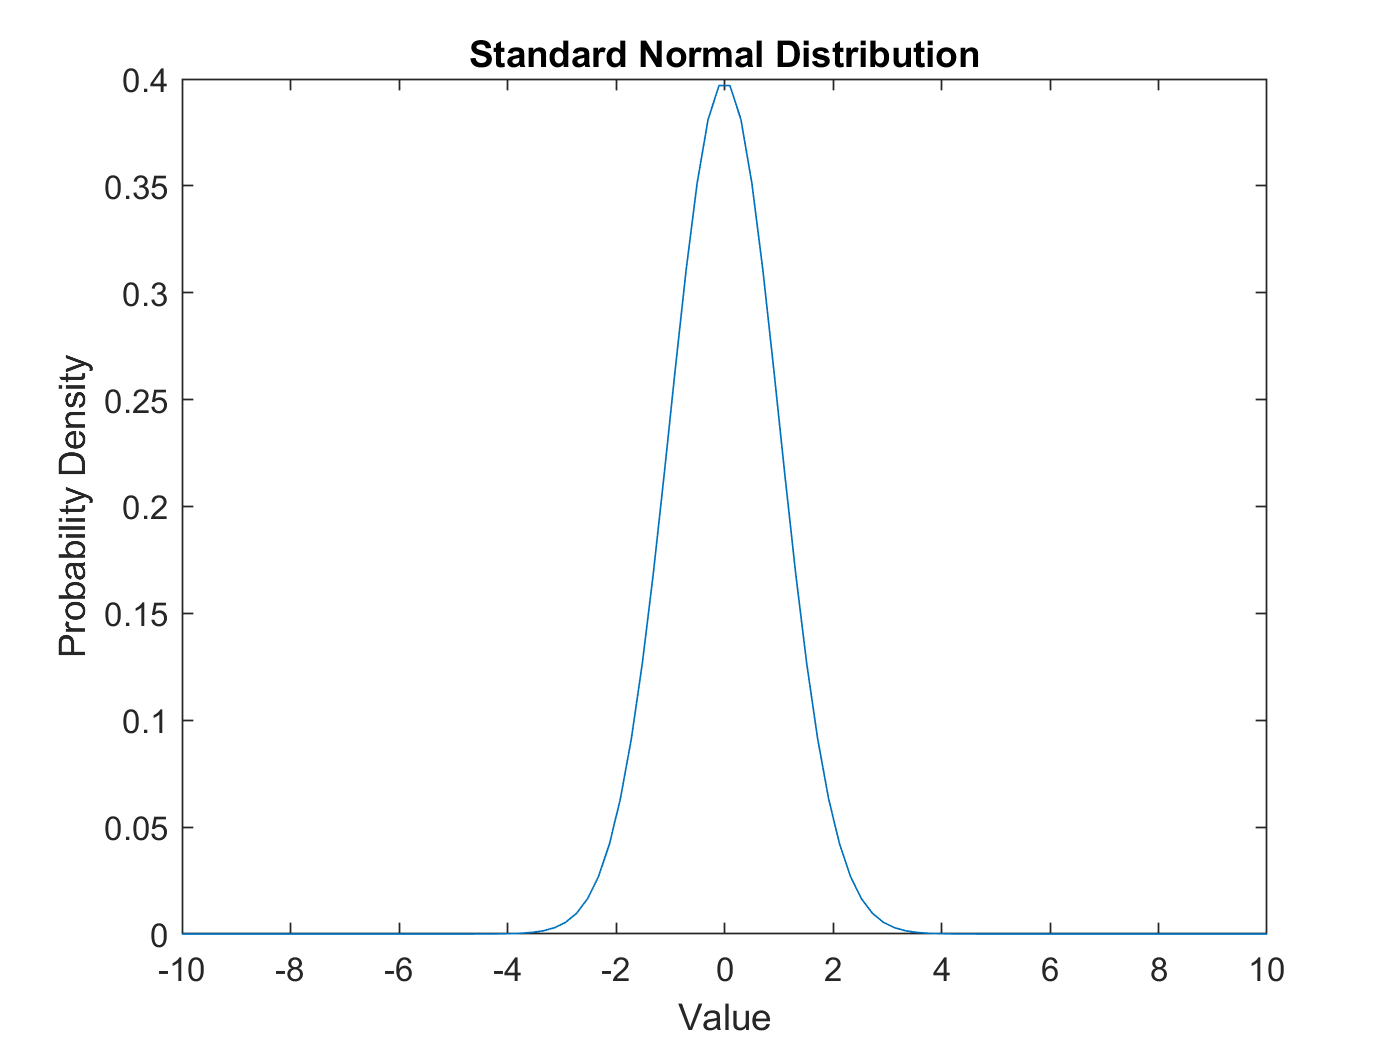

**B) Integrating Standard Normal Distributions**

We can use sigma values, or how many standard deviations away from the mean, to determine the probability that a measurement falls between the tail and our sigma value on our standard normal distribution. We do this by integrating the standard normal distribution up to the sigma value of our choosing. In MATLAB this is done using the normcdf() function where


$$\textrm{normcdf}\left(x\right)=\frac{1}{2}\textrm{erfc}\left(-\frac{x}{\sqrt{2}}\right)$$
 

and $\textrm{erfc}\left(x\right)=1-\textrm{erf}\left(x\right)=\frac{2}{\sqrt{\pi }}\int_x^{\infty } e^{-z^2 } \textrm{dz}$

The table below shows a few sigma values and the corresponding probability that a measurement has a value below that of the corresponding sigma value: 

SigmaValue = [1; 2; 3];
prob_succ = 0;
sigma = 1;
Probability = normcdf(SigmaValue,prob_succ,sigma);
T1 = table(SigmaValue,Probability);

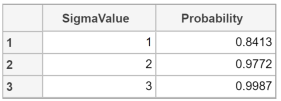

This can be confirmed by checking the corresponding z-table found here: [https://en.wikipedia.org/wiki/Standard_normal_table](https://en.wikipedia.org/wiki/Standard_normal_table) 

**C) Finding Sigma Values based on Probability **

We can also do the inverse of what we did in part b). We can use norminv() to determine the sigma value asssociated with a probability given. Let's use the probabilities from the last table to determine the previously chosen sigma values: 

SigmaValue = norminv(Probability,prob_succ,sigma);
T2 = table(Probability,SigmaValue);

 

This matches our first calculations. 

This, again, can be confirmed by checking the z-table found here: [https://en.wikipedia.org/wiki/Standard_normal_table](https://en.wikipedia.org/wiki/Standard_normal_table) 

**D) Negative Sigma Values**

Using norminv() will return a negative sigma value for any probability that is less than 0.5. For example:

Probability = 0.1586;
SigmaValue = norminv(Probability,prob_succ,sigma);
T3 = table(Probability,SigmaValue);

A probability of 0.1586 yields a sigma value of approximatly -1 because the sigma value is below the mean of 0. All that a negative sigma means is that the sigma value is to the left of the mean on a standard normal distribution.  

### 2) Exponential Distributions 

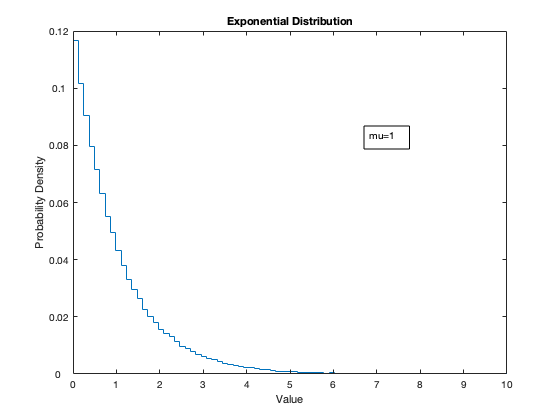

figure(2);
d = random('Exponential', 1, [1, 100000]);
histogram(d,100,'DisplayStyle',"stairs",'LineWidth',1);
xlim([0,10]);
ytix = get(gca, 'YTick'); 
set(gca, 'YTick',ytix, 'YTickLabel',ytix/100000);
title('Exponential Distribution');
xlabel('Value');
ylabel('Probability Density');
str = {'mu=1'};
annotation('textbox', [0.65, 0.6, 0.1, 0.1], 'String', str, 'FitBoxToText','on')

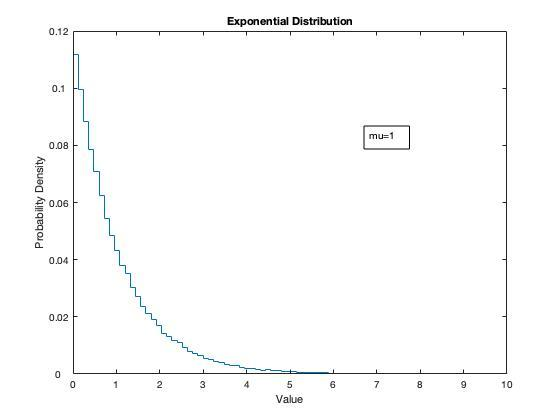

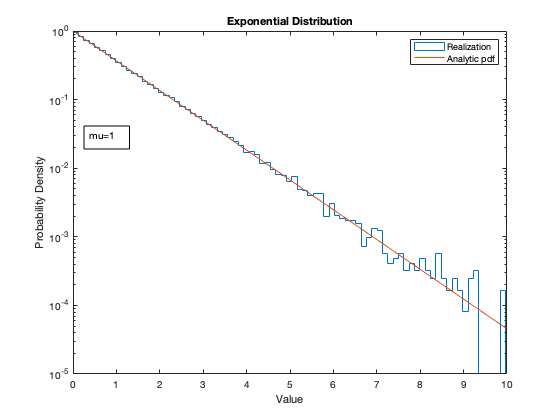

figure(3);
histogram(d,100,'DisplayStyle',"stairs",'LineWidth',1,"Normalization","pdf");
hold on;
x = linspace(0,10,100);
probden = makedist("Exponential","mu",1);
ProbDenFunc=pdf(probden,x);
plot(x,ProbDenFunc,"LineWidth",1);
set(gca,'YScale','log');
xlim([0,10]);
title('Exponential Distribution');
xlabel('Value');
ylabel('Probability Density');
legend('Realization','Analytic pdf');
str = {'mu=1'};
annotation('textbox', [0.15, 0.6, 0.1, 0.1], 'String', str, 'FitBoxToText','on')
hold off;

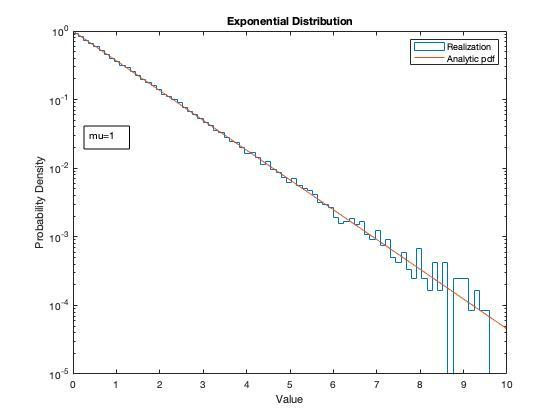

### 3) Hypothetical Statistical Question

**A) Value for Hypothetical Measurement**

The value I have selected as my hypothetical measurement is 6.  

**B) Statistical Question**

The most common use for exponential distribution are calculations involving the amount of time something takes. This could be calculating the probability that your phone will last x amount of years or the probability that the clerk at the store will spend x amount of minutes helping the next person in line. Let's use the latter for this example: 

What is the probability that the amount of time a clerk spends helping the next customer in line is less than 6 minutes long? Where the mean average time of helping a customer is 2 minute.  

**C) Mathematical Integral**

The probability density function for an exponential function is: 

$f\left(x\right)=m\;e^{-m\;x\;}$, where $m=\frac{1}{\mu }$

Since $\mu =2$ for this scenario the equation becomes: 


$$f\left(x\right)=\frac{1}{2}e^{\frac{-x}{2}\;}$$


The cumulative density function (cdf) is used in order to calculate probabilities for specific probability density functions. The cdf is the integral of the probability density function above: 


$$F\left(x\right)=\int_0^{\infty } \frac{1}{\mu }e^{\frac{-x}{\mu }\;} \;d\;x=1-\;e^{\frac{-x}{\mu }\;}$$


**D) Calculating Probability that the Background Produced the Signal**

In order to calculate the probability we use $F\left(x\right)\;\textrm{when}\;x=6\;\textrm{and}\;\mu =2$, 


$$F\left(6\right)=\int_0^{\infty } \frac{1}{2}e^{\frac{-6}{2}\;} \;d\;x=1-\;e^{\frac{-6}{2}\;} =0\ldotp 9502\;$$


Probability = cdf('Exponential', 6, 2)

Probability = 0.9502

We can check this with the code above with the function cdf(). The resulting probability is:

`Probability = 0.9502 `

This means our cumulative density function was correct. 

**E) Converting the Probability into an Equivalent 'Sigma'**

In order to convert our probability into a equivalent 'sigma' value, we must use norminv() once more. 

SigmaValue = norminv(Probability)

SigmaValue = 1.6469

Our corresponding sigma value for a probability of 0.9502 is: 

`SigmaValue = 1.6469`

### **4) Various Hypothetical Measurement Values**

**Don't forget this.**

## **Non-continuous Distributions **

### **1) Binomial Distribution**

**A) Binomial Distributions **

A binomial distribution is the probability of a success or failure outcome in an experiment that is repeated n nmber of times. It is called a binomial distribution since it only has two outcomes (success or failure, heads or tails, etc). A binomial distribution needs to meet three criteria: 

    1. The number of observations or trials is fixed. 

    2. Each observation is independent, meaning that no observation has an effect on another observation. 

    3. The probability of success is exactly the same from one trial to another. 

**B) Various Plots **

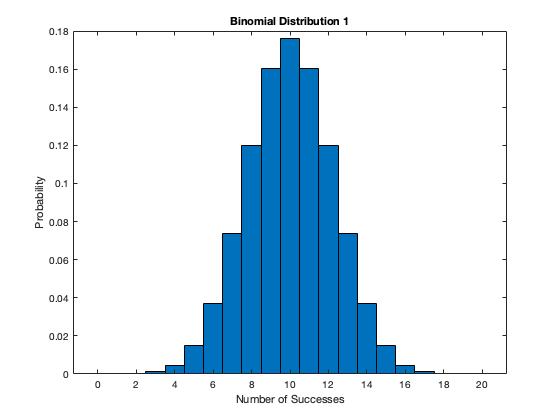

% Plot with success rate of 0.5 and n = 20 %
prob_succ = 0.5;
x = 0:20;
p = binopdf(x, 20, prob_succ);
figure(4)
bar(x, p, 1);
xlabel('Number of Successes');
ylabel('Probability');
title('Binomial Distribution 1');

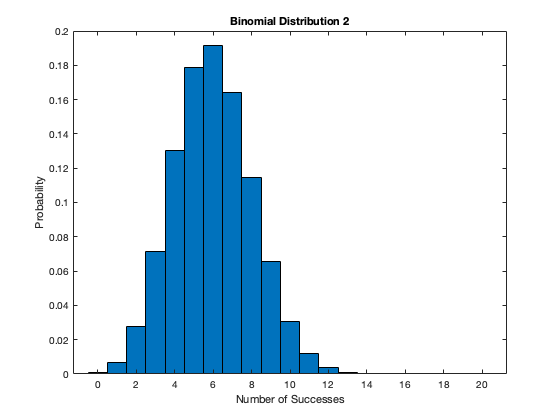


% Plot with success rate of 0.3 and n = 20 %
prob_succ = 0.3;
x = 0:20;
p = binopdf(x, 20, prob_succ);
figure(4)
bar(x, p, 1);
xlabel('Number of Successes');
ylabel('Probability');
title('Binomial Distribution 2');

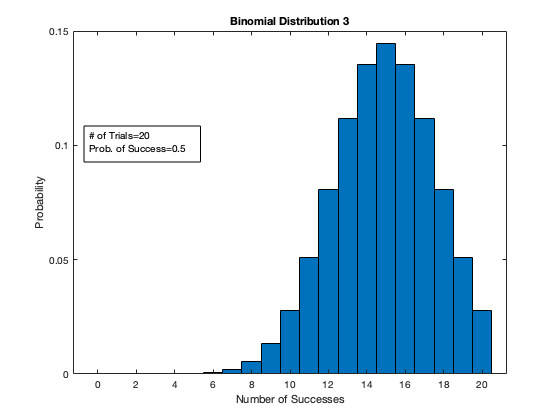


% Plot with success rate of 0.5 and n = 40 %
prob_succ = 0.5;
x = 0:20;
p = binopdf(x, 30, prob_succ);
figure(4)
bar(x, p, 1);
xlabel('Number of Successes');
ylabel('Probability');
title('Binomial Distribution 3');
str = {'# of Trials=40',  'Prob. of Success=0.5'};
annotation('textbox', [0.15, 0.6, 0.1, 0.1], 'String', str, 'FitBoxToText','on')

The three binomial distributions below all use the same 'x' values or number of sucesses ranging from 0 to 20 successes. 

Binomial Distribution 1 has a probability of success of 0.5 and 20 trials 

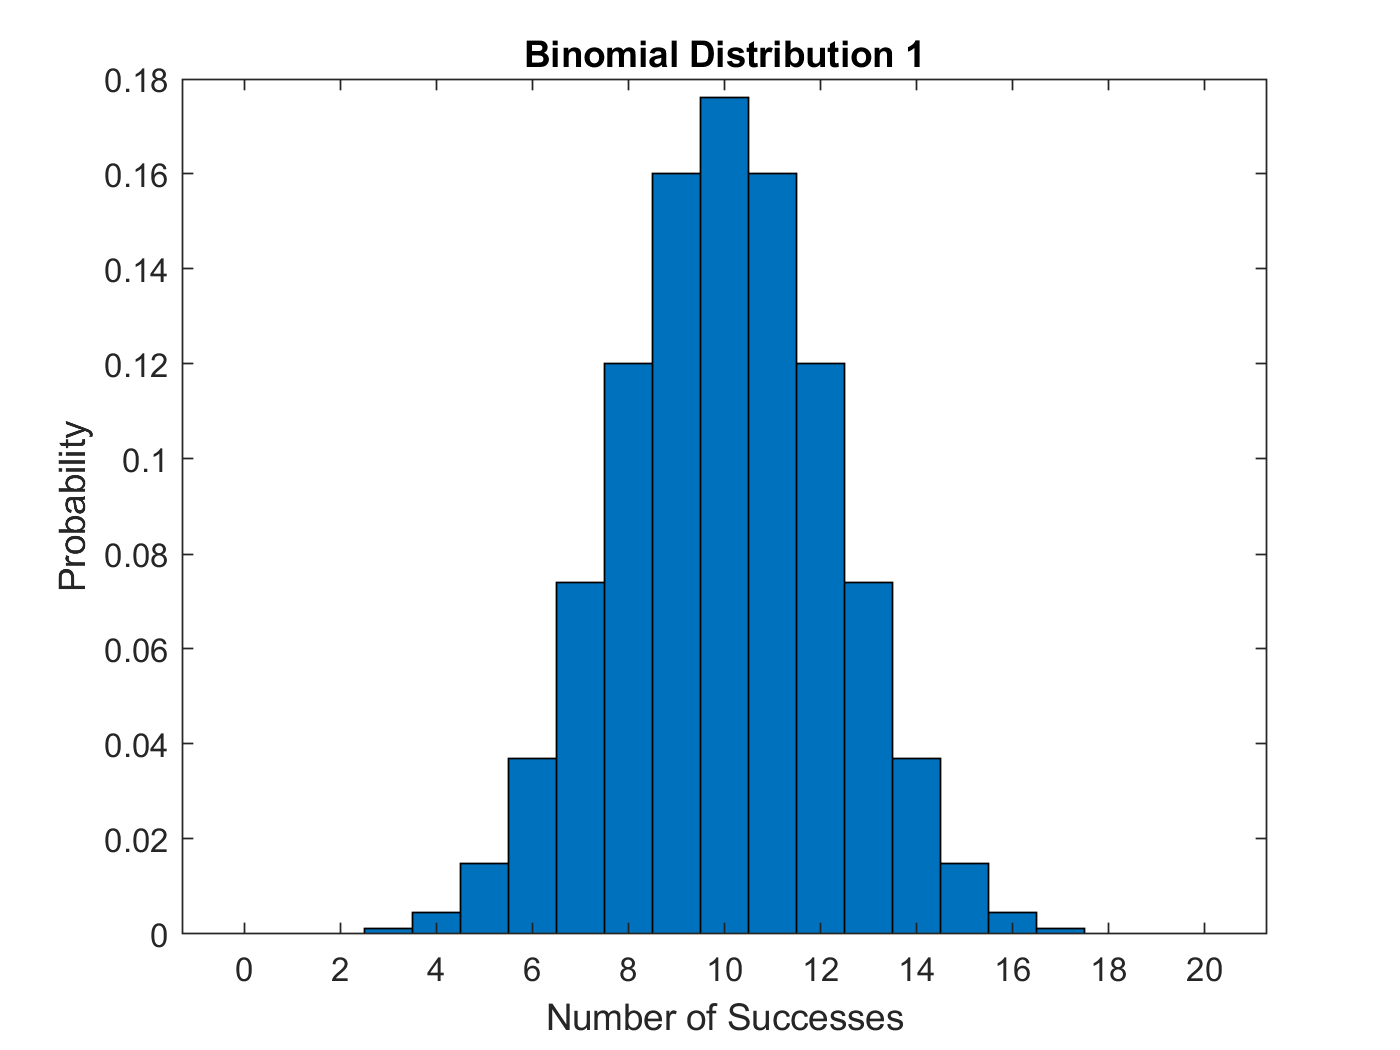

Binomial Distribution 2 has a probability of success of 0.3 and 20 trials 

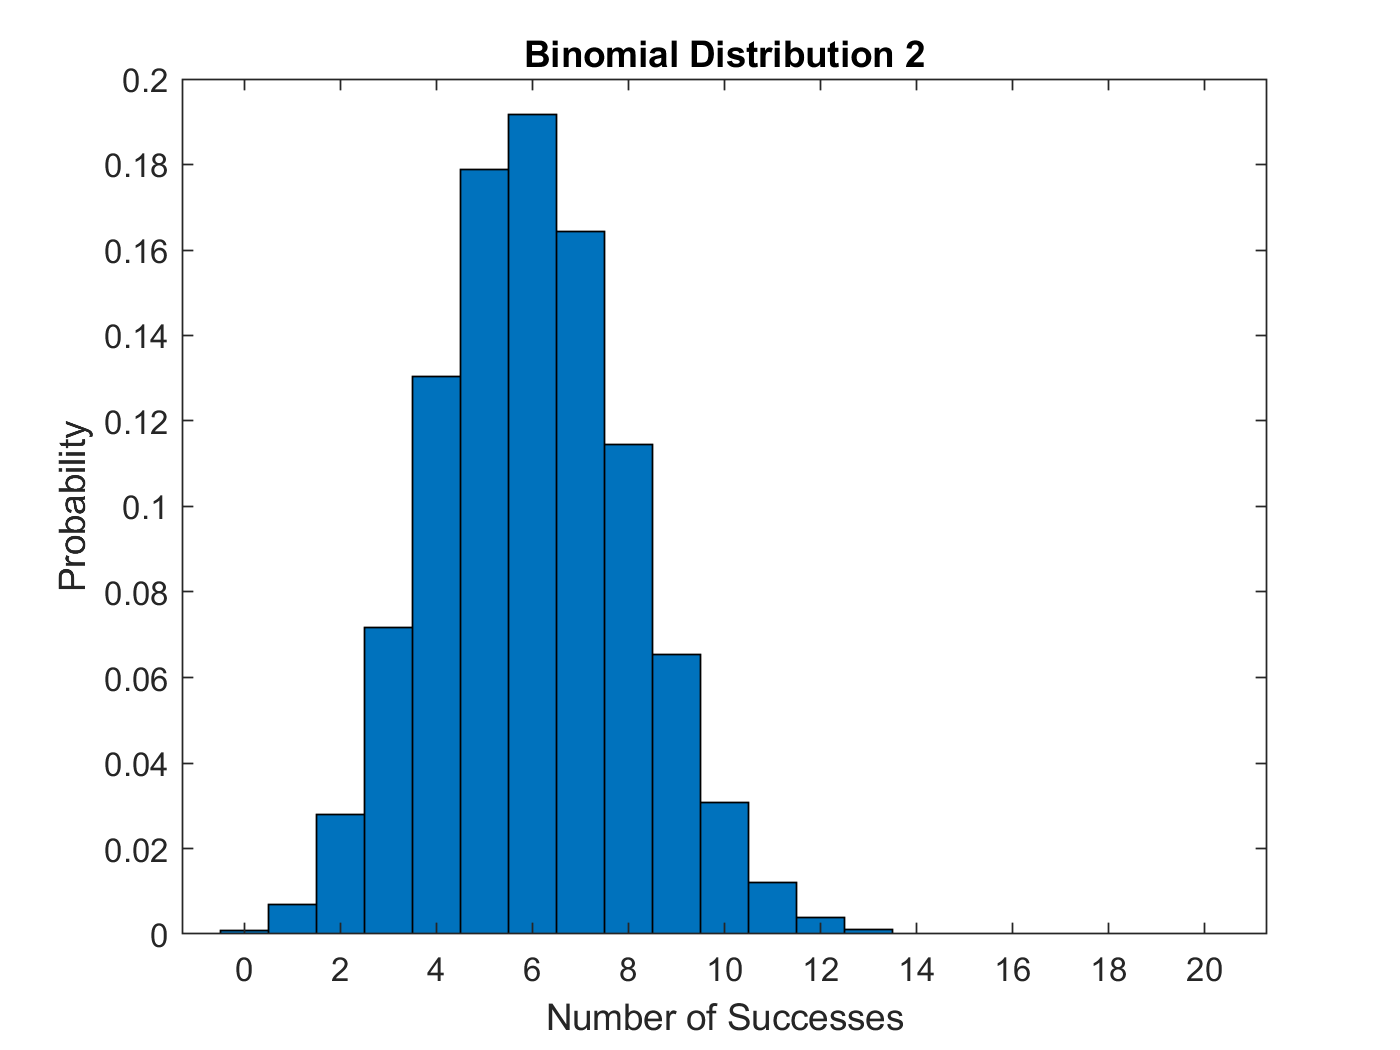

Binomial Distribution 1 has a probability of success of 0.5 and 30 trials 

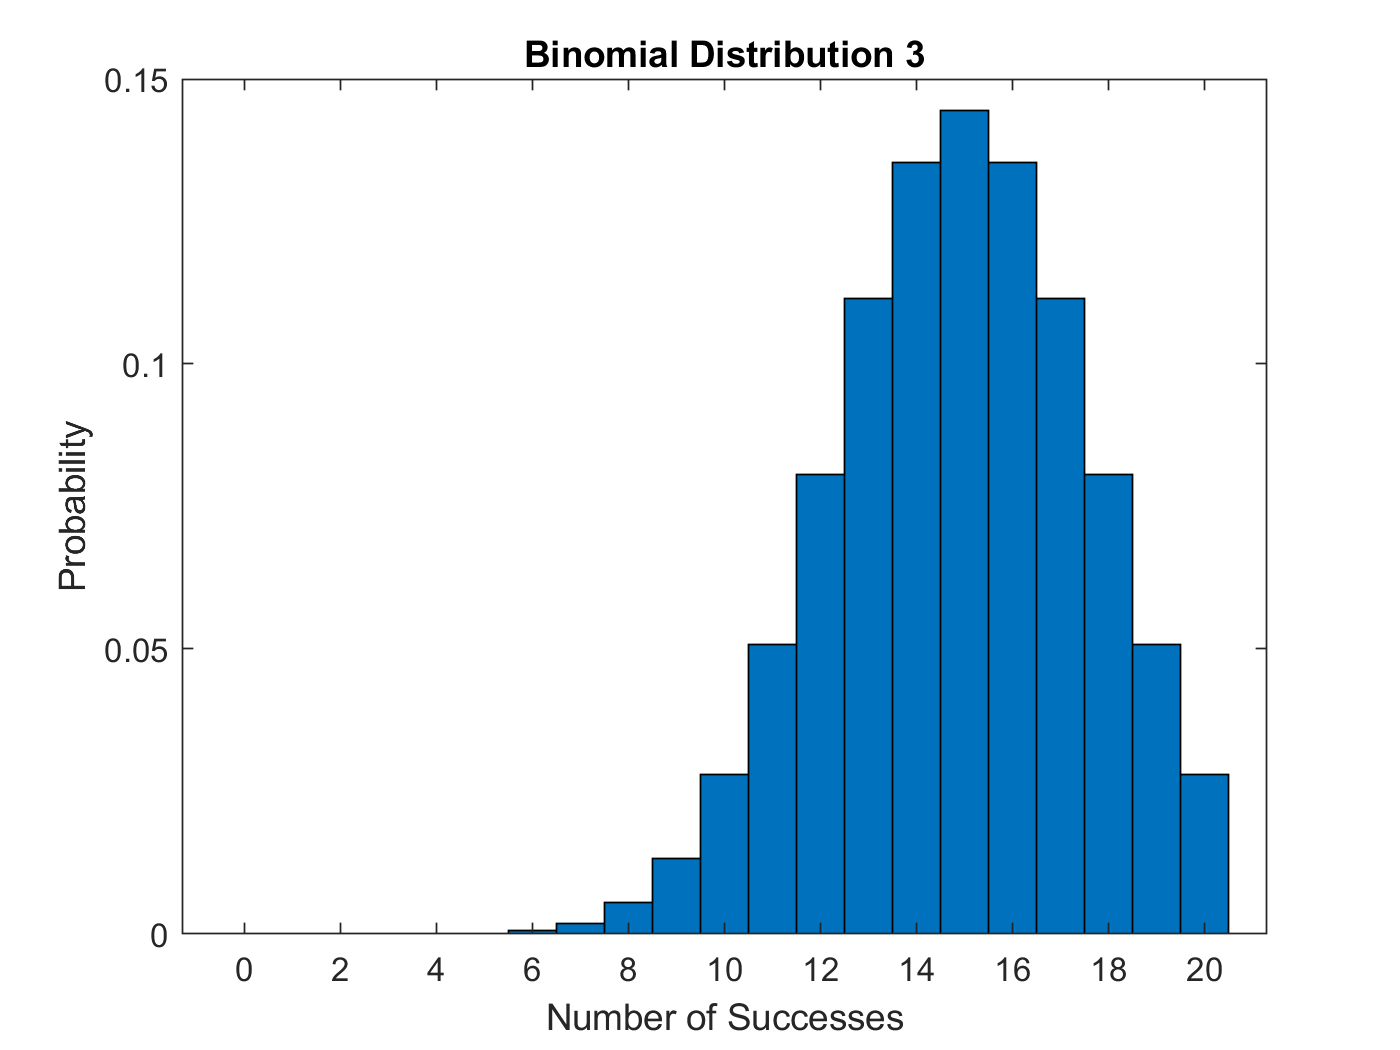

**C) Hypothetical Binomial Distribution Question**

**D) Descrete Probabilities and Sigmas **

**E) Continuous Parameters **